clear 
clc

syms M_c m g l r b_v b_w real
syms tau
syms x(t) theta(t) x_dot theta_dot x_ddot theta_ddot

params = [M_c; m; g; l; r; b_v; b_w];
values = [0.3; 0.1; 9.82; 0.03; 0.025; 0.001; 0.001];

% Differentiated variables
vars_diff = [diff(x,t,2); diff(x); x; diff(theta,t,2); diff(theta); theta];

% Inverse pendulum mass dynamics
posx_m = l*sin(theta) + x;
accx_m = diff(posx_m, t, 2); % second derivative

% Force required to accelerate the pendulums mass
F_pend = m*accx_m + b_v*diff(x, t);

% The force applied on the "cart" is
% the force generated by the motors
% minus the reaction force from the pendulum mass (x component)
F_mot = tau/r;
eq1 = M_c*diff(x,t,2) == F_mot - F_pend;

% Considering the load to be a point mass
eq2 = m*l^2*diff(theta,t,2) == m*g*l*sin(theta) - m*l*diff(x,t,2)*cos(theta) - tau - b_w*(diff(theta,t) - diff(x,t)/r);

% Collect terms
eq1 = collect(lhs(eq1) - rhs(eq1), vars_diff);
eq2 = collect(lhs(eq2) - rhs(eq2), vars_diff);

% Express symbolically
syms x theta
vars_sym = [x_ddot; x_dot; x; theta_ddot; theta_dot; theta];
eq1 = subs(eq1, vars_diff, vars_sym);
eq2 = subs(eq2, vars_diff, vars_sym);

% Get nonlinear equations
q = [x; theta];
q_dot = [x_dot; theta_dot];
q_ddot = [x_ddot; theta_ddot];

symb_states = [q; q_dot; tau];

[M, rest] = equationsToMatrix([eq1; eq2], [x_ddot; theta_ddot]);
model_nonlin_symb = M \ rest;
model_nonlin = subs(model_nonlin_symb, formula(params), values);

pendulum_dynamics = matlabFunction(model_nonlin, 'Vars', {x, theta, x_dot, theta_dot, tau});

% Get linearized M C G and B terms (first order TS)
% Linearize before inverting the M matrix

q_op = [0; 0];
q_dot_op = [0; 0];
tau_op = 0;

B = jacobian(rest, tau); % extract tau terms
rest_noinput = simplify(rest - B*tau); % remove input from rest terms

M0 = subs(M, formula([q; q_dot]), [q_op; q_dot_op]);
B0 = subs(B, formula([q; q_dot]), [q_op; q_dot_op]); % Already linear, but for completeness

G_nonlin = jacobian(rest_noinput, q);     % "stiffness" term
C_nonlin = jacobian(rest_noinput, q_dot); % "damping" term

% linearize at op point
G_lin = subs(G_nonlin, formula([q; q_dot]), [q_op; q_dot_op]);
C_lin = subs(C_nonlin, formula([q; q_dot; tau]), [q_op; q_dot_op; tau_op]);

Aq = simplify(M0 \ G_lin)

$$Aq = \left(\begin{array}{cc} 0 & -\frac{g\,m}{M_{c}}\\ 0 & \frac{g\,\left(M_{c}+m\right)}{M_{c}\,l} \end{array}\right)$$

Aq_dot = simplify(M0 \ C_lin)

$$Aq\_dot = \left(\begin{array}{cc} \frac{b_{w}-b_{v}\,l\,r}{M_{c}\,l\,r} & \frac{b_{w}}{M_{c}\,l}\\ -\frac{M_{c}\,b_{w}+b_{w}\,m-b_{v}\,l\,m\,r}{M_{c}\,l^{2}\,m\,r} & -\frac{b_{w}\,\left(M_{c}+m\right)}{M_{c}\,l^{2}\,m} \end{array}\right)$$

B_lin = simplify(M0 \ B0);

% Create first order state space model.
% states x, theta, x_dot, theta_dot
A_symbolic = [zeros(2), eye(2);
              Aq, Aq_dot]

$$A\_symbolic = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & -\frac{g\,m}{M_{c}} & \frac{b_{w}-b_{v}\,l\,r}{M_{c}\,l\,r} & \frac{b_{w}}{M_{c}\,l}\\ 0 & \frac{g\,\left(M_{c}+m\right)}{M_{c}\,l} & -\frac{M_{c}\,b_{w}+b_{w}\,m-b_{v}\,l\,m\,r}{M_{c}\,l^{2}\,m\,r} & -\frac{b_{w}\,\left(M_{c}+m\right)}{M_{c}\,l^{2}\,m} \end{array}\right)$$

B_symbolic = [zeros(2,1); B_lin]

$$B\_symbolic = \left(\begin{array}{c} 0\\ 0\\ \frac{l+r}{M_{c}\,l\,r}\\ -\frac{M_{c}\,r+l\,m+m\,r}{M_{c}\,l^{2}\,m\,r} \end{array}\right)$$


A = double(subs(A_symbolic, formula(params), values))

A =          0         0    1.0000         0
         0         0         0    1.0000
         0   -3.2733    4.4411    0.1111
         0  436.4444 -592.4815  -14.8148


B = double(subs(B_symbolic, formula(params), values))

B = 1.0e+04 *

         0
         0
    0.0244
   -1.9259


C = eye(4);

Ts = 0.01;

sys = ss(A,B,C,0);
dsys = c2d(sys, Ts)


dsys =
 
  A = 
               x1          x2          x3          x4
   x1           1  -0.0001587     0.01022   4.855e-06
   x2           0       1.021    -0.02873    0.009353
   x3           0    -0.03132       1.042   0.0009044
   x4           0       4.176      -5.669      0.8794
 
  B = 
            u1
   x1  0.01208
   x2  -0.9435
   x3    2.404
   x4   -187.1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



Obsv = rank(obsv(sys))

Obsv = 4

Cont = rank(ctrb(sys))

Cont = 4


Qx = [10, 0, 0, 0;
      0, 100, 0, 0;
      0, 0, 0.1, 0;
      0, 0, 0, 0.1];
Qu = 0.1;

[Kd, ~, ~] = dlqr(dsys.A, dsys.B, Qx, Qu)

Kd =    -0.0461   -0.1707    0.0158   -0.0056



% Check stability
eig(dsys.A - dsys.B*Kd)

ans =     0.0000
    0.7279
    0.9977
    0.9697


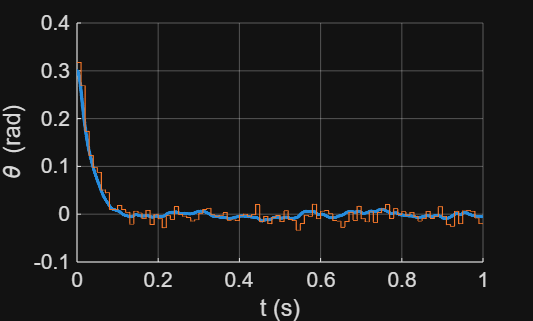


% Simulate nonlinear system
t_end = 1;
T = 0:Ts:t_end;
x0 = [0; 0.3; 0; 0];
x = x0;

t_plot = [];
X = [];
Y = [];
U = [];

for k = 1:length(T)-1
    % Compute control at the start of interval from noisy measurment
    n = normrnd(0, 0.01, [1,4]);
    y = x + n.';
    u = -Kd*y;
    
    % Integrate nonlinear system over [T(k), T(k+1)] with constant u
    ode = @(t,x) [
        x(3)
        x(4)
        pendulum_dynamics(x(1), x(2), x(3), x(4), u)
        ];

    [tk, xk] = ode45(ode, [T(k), T(k+1)], x); % Simulate from "true" state
    
    % Append trajectory
    t_plot = [t_plot; tk];
    X = [X; xk];
    Y = [Y; repmat(y.', length(tk),4)];
    
    % Append control (piecewise constant)
    U = [U; u*ones(length(tk),1)];
    
    % Update state for next interval
    x = xk(end,:)';
end

%% Plot
figure(1);
hold on
plot(t_plot, X(:,2), 'LineWidth',1.5);
plot(t_plot, Y(:,2));
xlabel('t (s)');
ylabel('\theta (rad)');
grid on;

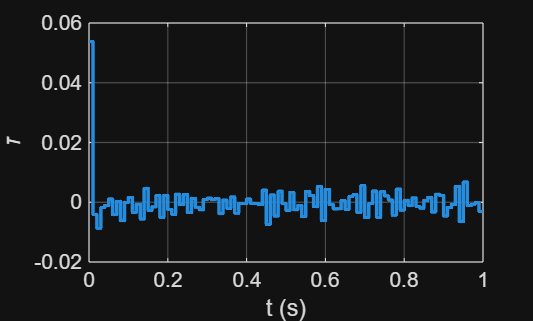


figure(2)
plot(t_plot, U, 'LineWidth',1.5);
xlabel('t (s)');
ylabel('\tau');
grid on;